% Osservazione: è necessario avere la versione di FSDA 8.7.6.7

## Esercizio I

Caricare la table denominata cinema tramite l'ìstruzione load cinema.mat

load cinema.mat
% I dati riportati nella tabella di contingenza cinema riportano i risulati
% di un sondaggio in cui si chiedeva agli spettatori la loro opinione su un
% film che avevano appena visto. Al pubblico è stato anche chiesto di
% indicare la propria fascia d'età.
% 

Assegnare alle colonne della table i nomi "Brutto" "Medio" "Bello" "MoltoBello" (punti 3)

cinema.Properties.VariableNames=["Brutto" "Medio" "Bello" "MoltoBello"];


Rinominare la table con le prime due lettere (senza accenti) del proprio cognome. Attenzione: rinominare non copiare (punti 1)


RI=cinema;
clear cinema 

Calcolare manualmente l'ìndice Chi2 e commentare il relativo p-value (punti 5)

N=RI{:,:};
n=sum(N,'all');
Ntheo=sum(N,2)*sum(N,1)/n;
% Calcolo indice Chi2 manualmente (v. equazione 8.25)
Chi2=sum(((N-Ntheo).^2)./Ntheo,'all');
disp(['Indice Chi2:' num2str(Chi2)])

Indice Chi2:148.2676


[I,J]=size(N);
gdl=(I-1)*(J-1);
pval=chi2cdf(Chi2,gdl,'upper');
disp(['pvalue=' num2str(pval)])

pvalue=1.6126e-22


% p-val bassissimo. Rifiuto decisamente l'ipotesi nulla di assenza di
% relazione tra la fascia di età ed il gradimento al film

Effettuare un'analisi delle corrispondenze (punti 2)

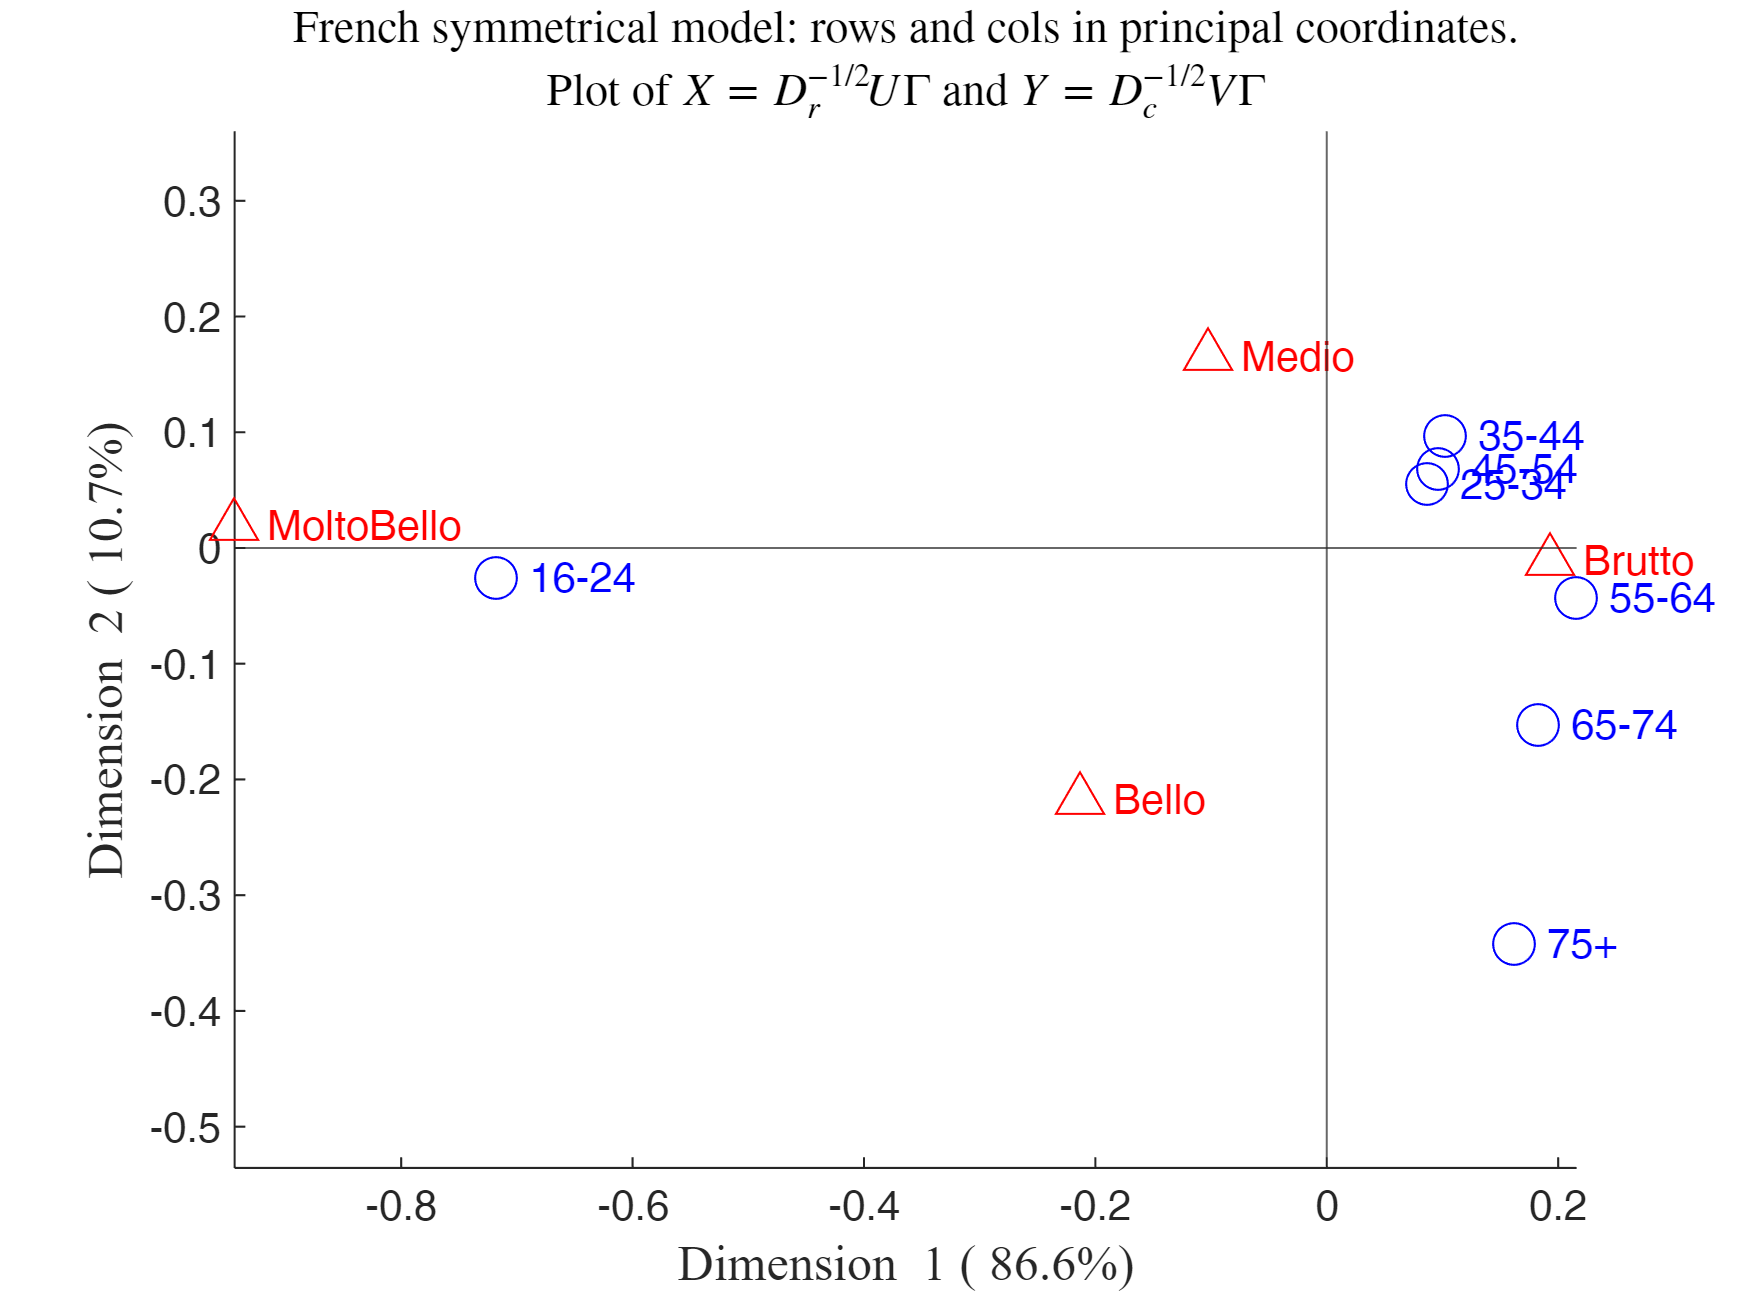

Summary
             Singular_value     Inertia     Accounted_for    Cumulative
             ______________    _________    _____________    __________

    dim_1        0.30768        0.094664        0.8664         0.8664  
    dim_2          0.108        0.011663       0.10674        0.97315  
    dim_3       0.054165       0.0029338      0.026851              1  

ROW POINTS
Results for dimension: 1
              Scores     CntrbPnt2In    CntrbDim2In
             ________    ___________    ___________

    16-24    -0.71758      0.82974        0.99865  
    25-34    0.086735     0.013411        0.54854  
    35-44     0.10269     0.022657        0.4

out=CorAna(RI);

Calcolare e commentare l'indice di Cramer (punti 4)

% Indice di Cramer
disp('Indice di Cramer')

Indice di Cramer


disp(out.CramerV)

    0.1908



% In alternativa il valore dell'indice di Cramer poteva essere recuperato
% dalla chiamata a corrNominal
% Associazione pari al 19 per cento del valore massimo possibile


Commentare il significato della prima dimensione latente (punti 3)

% Andando da sinistra verso destra il gradimento al film diminuisce
% Andando da sinistra verso destra l'età aumenta.
% La prima dimensione latente è sia l'eta: da giovani a maturi
% sia il gradimento al film (da MoltoBello a Brutto) 


Discutere la fascia di età a cui è piaciuto maggiormente il film  (punti 3)

% 16-24 anni. Il film è piaciuto molto ai ventenni ma non a coloro che
% presentano una fascia di età superiore.


Aggiungere al grafico di analisi delle corrispondenze l'ellisse di confidenza associato ai primi 3 punti riga (punti 3)

confellipse=struct;
confellipse.selCols='';
confellipse.selRows=1:3;
CorAnaplot(out,'confellipse',confellipse)
% Commento l'ellissi di confidenza dei ventenni è molto distante dagli
% ellissi di confidenza delle classi di età successive. La distqnza tra la
% fascia di età 16-24 è molto maggiore  di quella tra le due fascie di età
% successive.


Aggiungere come titolo del grafico il proprio nome/cognome e numero di matricola (punti 1)

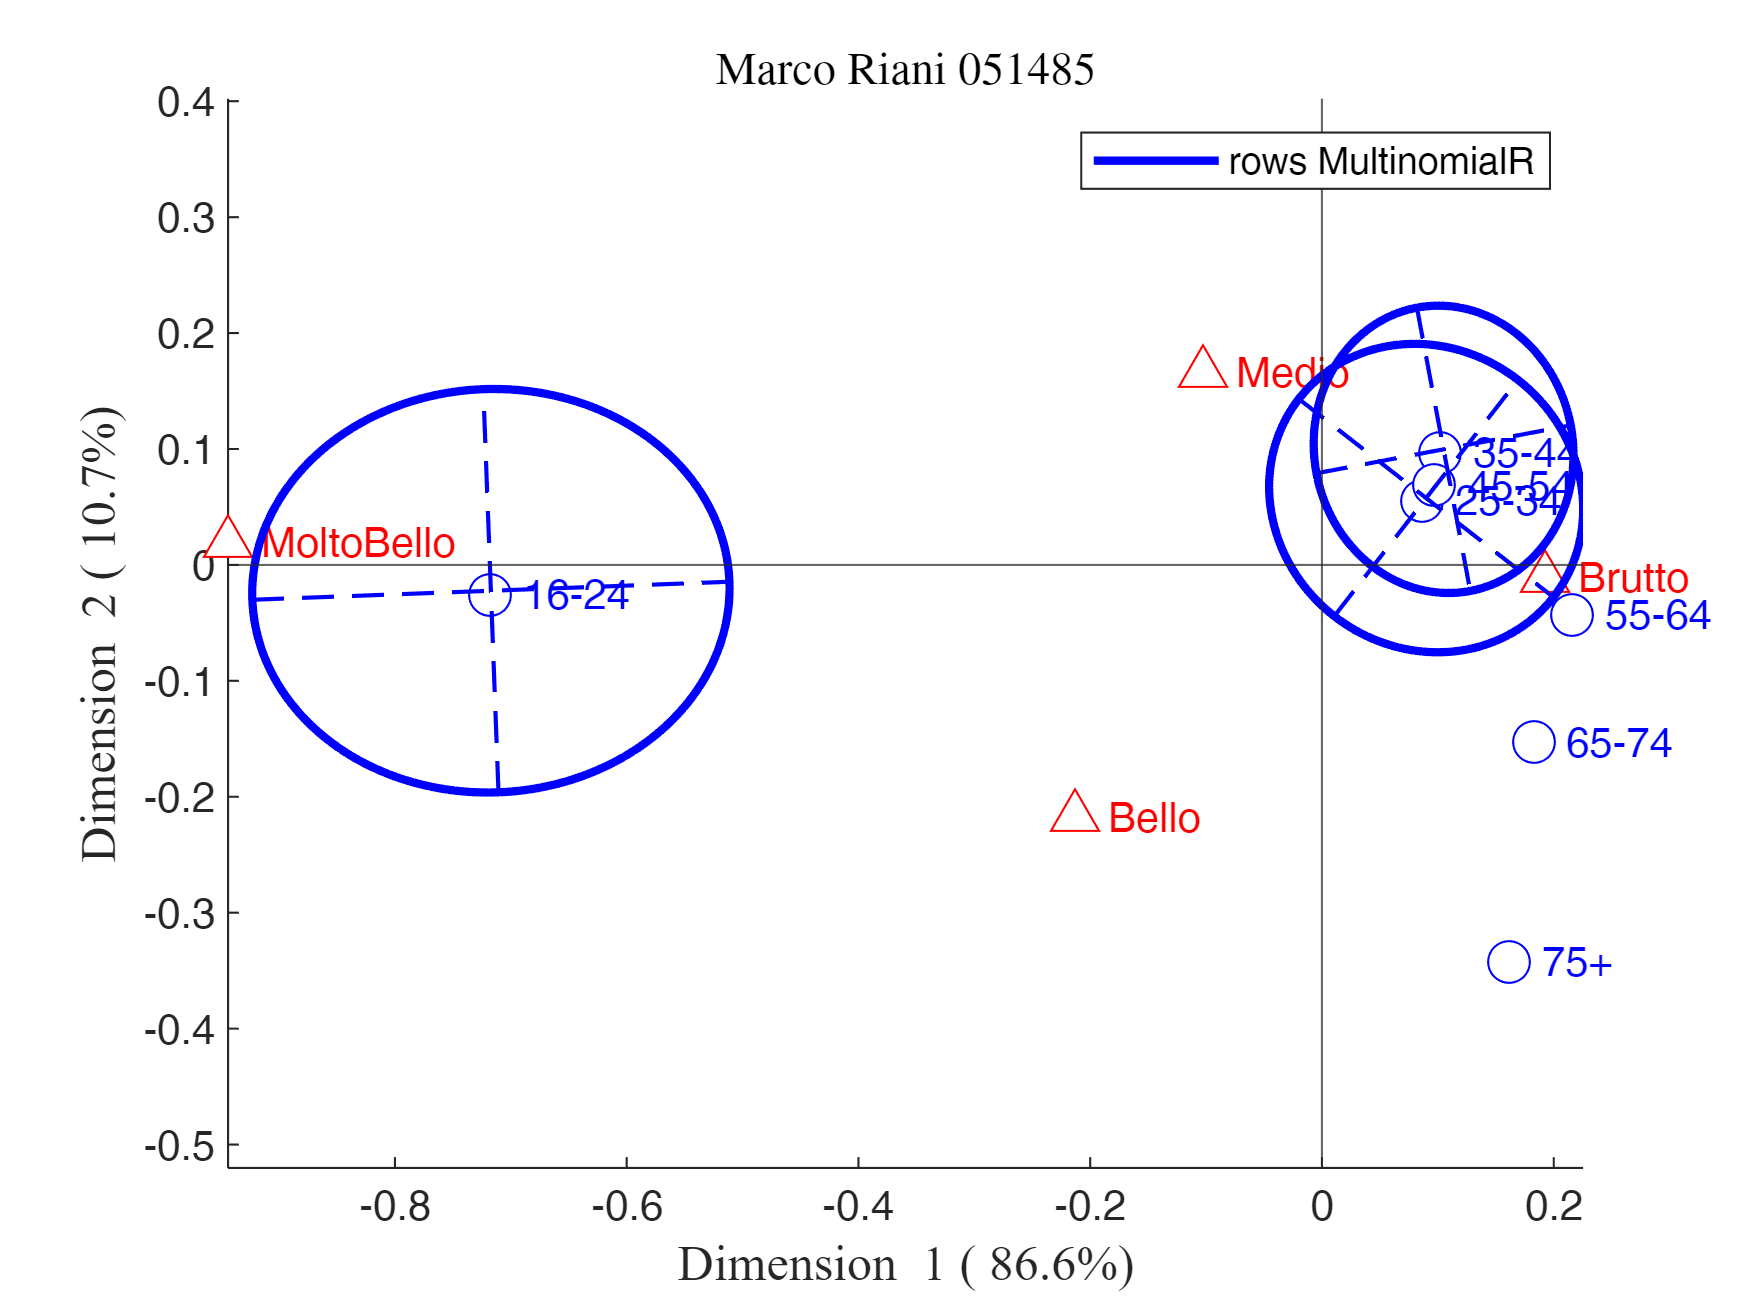

title('Marco Riani 051485')

## ESERCIZIO II

Generare una matrice di dimensione 200x4 denominata con le prime 3 lettere del proprio nome da una distribuzione normale multivariata con vettore delle medie (1 2 3 4) e matrice di covarianze una matrice diagonale con i seguenti valori delle varianze (1 2 3 4). Per replicabilità dei risultati utilizzare il seed 100. Calcolare le medie e le varianze campionarie (punti 5)

rng(100);
medie=1:4;
Sigma=diag(medie);
MAR=mvnrnd(medie,Sigma,200);
disp('Medie campionarie')

Medie campionarie


disp(mean(MAR))

    0.9819    1.9883    2.9155    4.1285



disp('Varianze campionarie')

Varianze campionarie


disp(var(MAR))

    0.9429    2.1508    3.1493    3.2529

